# Nichtlineare Analyse Gitterstütze

clear
addpath('../../../../04-software/bofem/src')

import bofem.*;
import bofem.analysis.*;

fig = @(f) exportgraphics(gcf, ...
    ['../00-pics/truss-column/', f, '.png'] ...
    , 'Resolution', 300 ...
);

## Modell erzeugen

function m = makeSystem(e0)
    import bofem.*;

    % Modellparameter
    F = 50;
    w = 1.0;
    h = -40.0;
    nn = 41;

    % Material und Querschnitte
    m = Model();
    m.addMaterial(Material.STEEL_S235);
    m.addSection('CT', 'Gurte', 0.051, 0.0036);
    m.addSection('CT', 'Diagonalen', 0.03, 0.00176);

    % Knoten
    z = linspace(0, h, nn);
    x = e0 * (1 - cos(0.5 * pi * z / h));
    m.addNodes(x, z);
    m.addNodes(x + w, z);

    % Elementtyp
    m.useElementType = 'Truss2D';

    % Gurte in entgegengesetzter Richtung fuer Plots
    m.useSection = 1;
    m.addElements(1:nn-1, 1);
    m.addElements(1 + 2 * nn - (1:nn-1), -1);

    % Streben
    m.useSection = 2;
    m.addElements(2:nn, nn);
    m.addElements(1:nn-1, 1 + nn);
    m.addElements((1:nn-1) + nn, 1 - nn);

    % Auflager und Kraft
    m.setConstraint([1, nn+1], [true, true]);
    m.setForce([nn, 2*nn], [0, F]);
end

## System darstellen

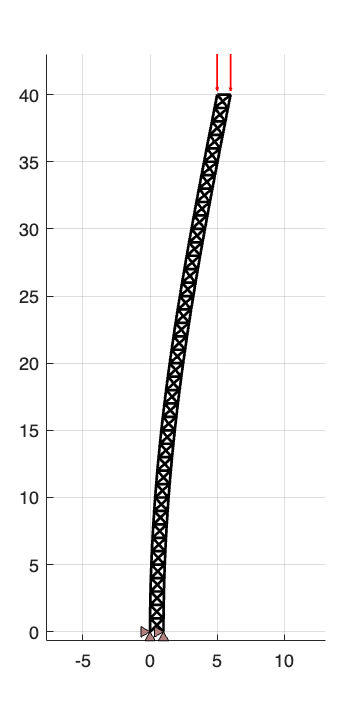

m = makeSystem(5);
figure('Position',[0 0 200 400])
v = Visualizer(m);
v.update()
axis on
grid on
title([])
fig('system')
reset(gcf)

## Lineare Analyse

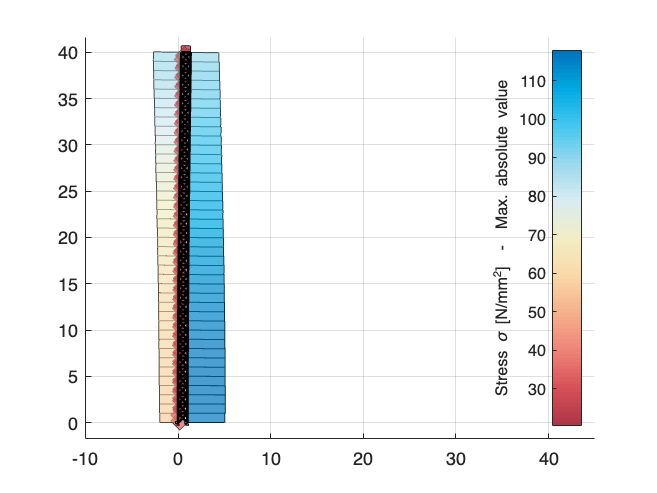

m = makeSystem(0.16);
m.solve();

% Verformung und Spannung
figure()
v = Visualizer(m);
v.drawElementsDeformed = true;
v.scaleElementResult = -4;
v.drawElementResult = 'sigma';
v.scaleU = 1;
v.update()
xlim([-10, 45])
title([])
axis on
grid on
fig('sigma-linear')

## Nichtlineare Berechnung

m = makeSystem(0.16);
m.analysis = NonlinearAnalysis();
m.analysis.nSteps = 200;
m.analysis.lambdaEnd = 1;
m.solve();

Horizontale Verschiebung rechts oben

idx = 159;

Verformung und Spannung

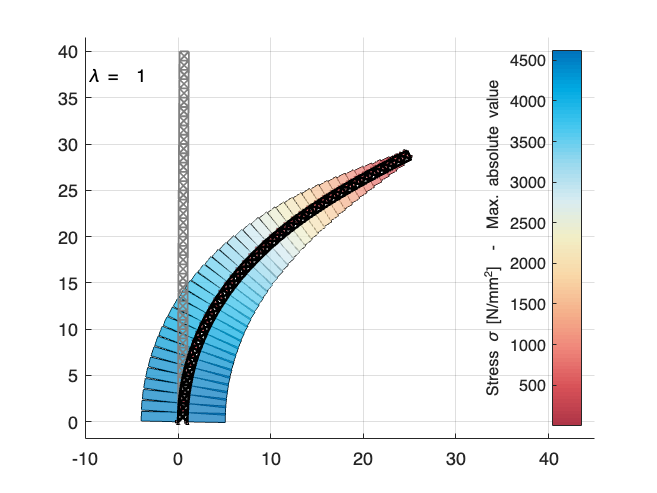

figure()
v = Visualizer(m);
v.drawElementsDeformed = true;
v.drawElementResult = 'sigma';
v.scaleElementResult = -4;
v.scaleU = 1;
v.update()
xlim([-10, 45])
title([])
axis on
grid on
fig('sigma-nichtlinear')

Last-Verformungs-Diagramm

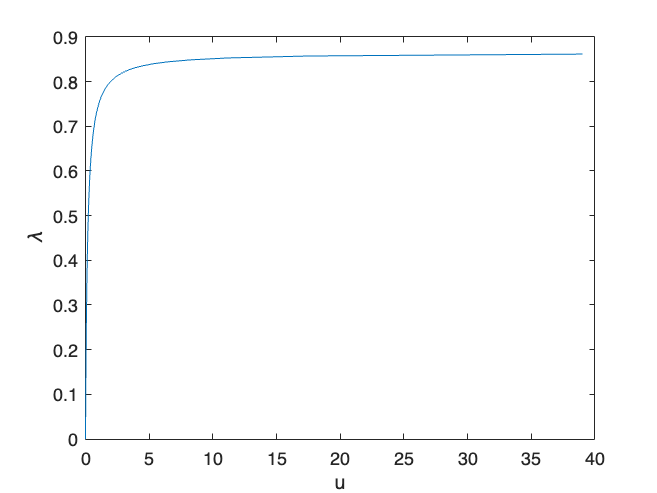

lnl = m.analysisResult.values;
unl = m.analysisResult.solutions(:, idx);
figure()
plot(unl, lnl)
xlabel('u')
ylabel('\lambda')
fig('last-verformung-1')

Verschiedene Vorverformungen

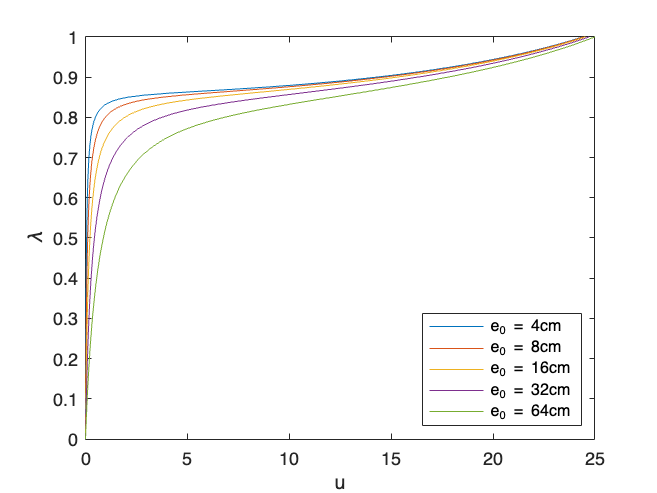

figure()
for e0 = [0.04, 0.08, 0.16, 0.32, 0.64]
    m = makeSystem(e0);
    m.analysis = NonlinearAnalysis();
    m.analysis.nSteps = 200;
    m.analysis.lambdaEnd = 1;
    m.solve();
    [~, idx] = max(abs(m.analysisResult.solutions(end,:)));
    l = m.analysisResult.values;
    u = m.analysisResult.solutions(:, idx);
    plot(u, l)
    hold on
end
hold off

xlim([0, 25]);
xlabel('u');
ylabel('\lambda');
lgd = legend('e_0 = 4cm', 'e_0 = 8cm', 'e_0 = 16cm', 'e_0 = 32cm', 'e_0 = 64cm');
lgd.Location = 'southeast';
fig('last-verformung-2')

## Berechnung nach Theorie II. Ordnung

m = makeSystem(0.16);
m.analysis = SecondOrderAnalysis();
m.analysis.nIterations = 1;
m.analysis.nSteps = 200;
m.analysis.lambdaEnd = 0.8615;

m.solve()

Verformung und Spannung

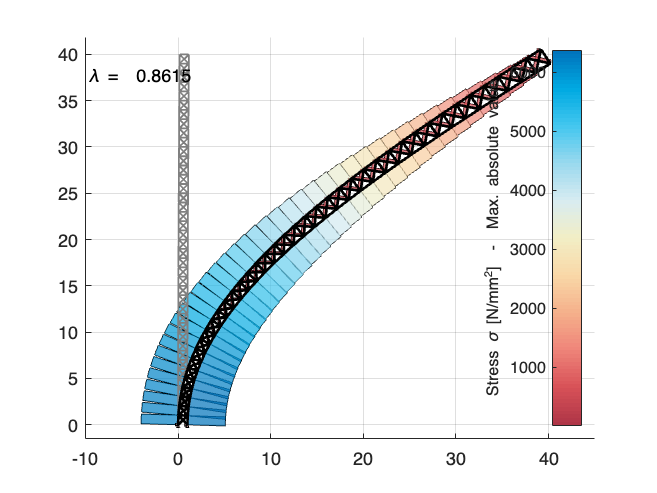

figure()
v = Visualizer(m);
v.drawElementsDeformed = true;
v.drawElementResult = 'sigma';
v.scaleElementResult = -4;
v.scaleU = 1;
v.update()
xlim([-10, 45])
title([])
axis on
grid on
fig('sigma-ii')

Last-Verformungs-Diagramm

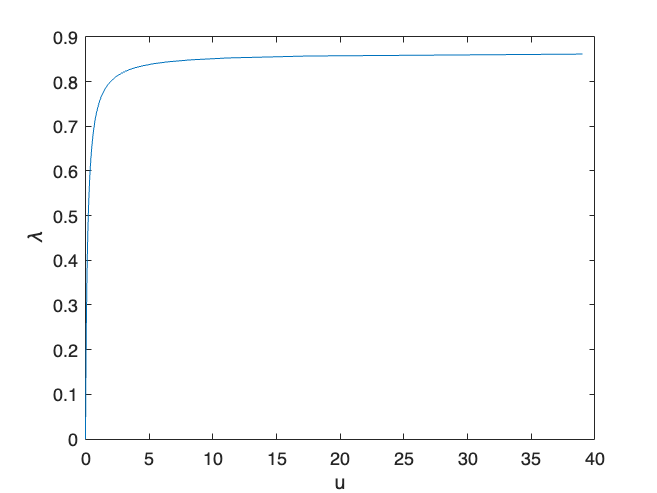

figure()
l = m.analysisResult.values;
u = m.analysisResult.solutions(:, idx);
plot(u, l)
xlabel('u')
ylabel('\lambda')
fig('last-verformung-3')

Mit nichtlinearer Lösung

figure()
plot(u, l, unl, lnl)
xlabel('u')
ylabel('\lambda')
lgd = legend('Theorie II. Ordnung', 'Nichtliner');
lgd.Location = 'southeast';
xlim([0, 25])
fig('last-verformung-4')

Zoom in

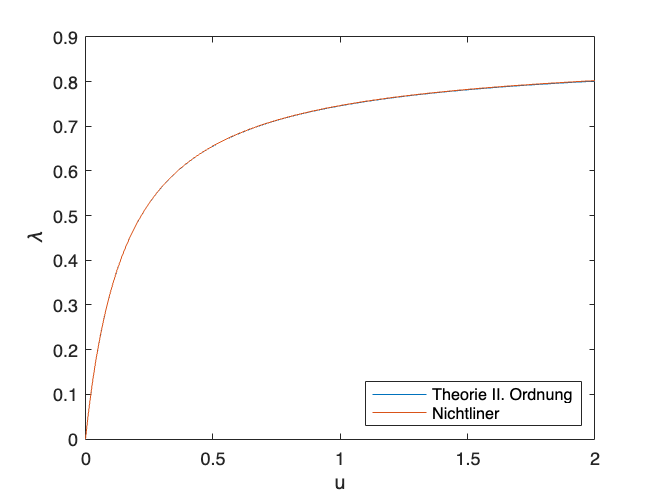

figure()
plot(u, l, unl, lnl)
xlabel('u')
ylabel('\lambda')
lgd = legend('Theorie II. Ordnung', 'Nichtliner');
lgd.Location = 'southeast';
xlim([0, 2])
fig('last-verformung-5')

## Verzweigungslastfaktor

m = makeSystem(0.0);
m.analysis = BucklingAnalysis();
m.solve()

Darstellung Knickfigur

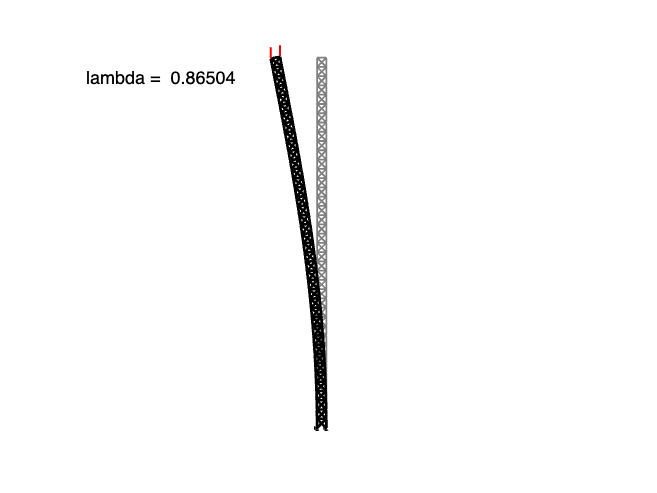

figure()
v = Visualizer(m);
v.drawElementsDeformed = true;
v.scaleU = 5;
v.update()
xlim([-25, 30])
title([])
fig('knickfigur')

Verzweigungslastfaktor und Knicklast

m.analysisResult.values(1)

ans = 0.8650

100 * m.analysisResult.values(1)

ans = 86.5043

Knicklast Eulerfall 1

E = m.material(1).E

E = 2.1000e+11

A1 = m.section(1).A

A1 = 5.3608e-04

I = 2 * 0.5^2 * A1

I = 2.6804e-04

Fcrit = pi^2 * E * I / (4 * 40^2) * 1e-3

Fcrit = 86.8040